# galvoCal Script

Generated in MATLAB R2022b on 10-27-2023

This script finds pixel-galvo voltage pairings and saves them to a matrix.

## Should already be connected to camera and laser

## Test Laser

Test Matlab control of laser

% outputs= [3 1 0 0];
% write(dq, outputs);

% outputs= [0 0 0 0];
% write(dq, outputs);

## Preview Laser

 Visualize laser spot and set-up proper laser intensity for calibration.

% start(v);

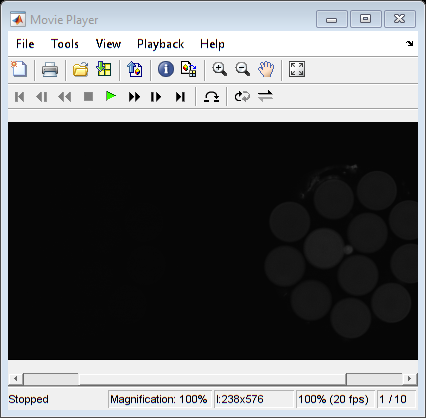

% 
% outputs = zeros(1,4);
% outputs(2) = 1; % digital input to laser to switch laser on
% outputs(1) = 0.04; % analog input to laser, low power to visualize spot better (0.04 V)
% outputs(3) = 0;
% outputs(4) = 0;
% 
% 
% write(dq,outputs); % turn laser on for 5s
% pause(5);
% outputs = zeros(1,4);
% write(dq,outputs); % turn laser off
% 
% stop(v);
% 
% recording = getdata(v, v.FramesAvailable);
% implay(recording);

## Run through Grid

 Acquire images for each position of the laser and save them to an array.

VxMin        = -2; % allowed range: -10 to 10. can try different values within that to see where edges of image are
VxMax        = 3; 
VyMin        = -2.55;
VyMax        = 2.5;
GridSpacingx  = 0.5; % V, what you want voltage increments to be when running horizontally through the grid
GridSpacingy  = 0.5; % V, what you want voltage increments to be when running vertically through the grid
GridSizeX    = ((VxMax - VxMin)/GridSpacingx) + 1;
GridSizeY    = ((VyMax - VyMin)/GridSpacingy) + 1;
data         = {};
GalvoVoltage = {};

h = figure; 
% Set laser control outputs
outputs(2) = 1; 
outputs(1) = 4;

% Loop through grid of galvo voltages
for iX = 1:GridSizeX
  for iY = 1:GridSizeY
      % Calculate Vx and Vy increments
      Vx = (VxMax-VxMin)*(iX-1)/(GridSizeX-1) + VxMin;
      Vy = (VyMax-VyMin)*(iY-1)/(GridSizeY-1) + VyMin;

      % Set voltage for DAQ galvo output channels
      outputs(3) = Vx;
      outputs(4) = Vy;

      % Turn laser on and take snapshot, then turn laser off
      write(dq, outputs);
      pause(0.2)
      snapshot = getsnapshot(v);
      pause(0.1);
      write(dq, [0  0 Vx Vy]); % turn laser off but keep galvo position
      figure(h), imshow(snapshot);
      title('Different positions of the beam are being scanned.')
   

      % This will save image (with laser beam position) and voltages.
      data(iX, iY) = {snapshot};
      GalvoVoltage(iX, iY) = {[Vx, Vy]};

  end
end

Specify scan data as an MxN double matrix, where M is the number of scans and N is the number of output channels.


write (dq,[0 0 0 0]); % laser off and back to 0 galvo voltage

% Save to global var for access by GUI
lsr.data = data;
lsr.GalvoVoltage = GalvoVoltage;

## Calculate Laser Pixel Positions

 Go through each image, locate pixel position of the laser, and create a matrix: [pixel_x pixel_y galvo_Vx galvo_Vy], where each row corresponds to a grid point. Save matrix to directory!

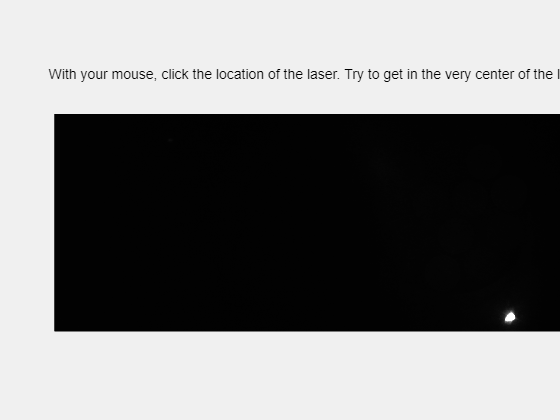

% camera is 576 pixels wide x 238 pixels tall
% n_vx = 238; n_vy = 576 
% Vx moves beam horizontally (+ = left from center, - = right from center
% Vy moves beam vertically (+ = up from center, - = down from center

% Do manually in GUI for now:
findLaserPoints;


% cal_mtx = [];
% for x = 1:size(data,1)
%     for y= 1:size(data,2)
%         % Find laser from snapshot
%         img = data(x,y);
%         [centers, ~] = imfindcircles(img,[5 50]); % can adjust radius limits
% 
%         % Get corresponding galvo voltage
%         galvoVolt = GalvoVoltage(x,y);
% 
%         % Save to new matrix
%         cal_mtx = [cal_mtx ; centers(1,2) centers(1,1) galvoVolt(1,1) galvoVolt(1,2)]; % pixel_y (since galvo X is vertical axis), pixel_x, Gx, Gy
%         filename = sprintf('cal_mtx_%s.mat', datetime('now','Format','MMddyy'));
%         save(filename, 'cal_mtx');
%     end
% end